# GP-UKF static ver.

sat-obs-Sun position is fixed and satPos is origin.

軌道運動はとりあえず考えない

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../../gpryui/'));

% create directory
% mkdir ../results/GPUKF_staticFixed/

tStart = tic;

### constants

earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

### simulation conditions

model = "boxWing"; % flatPlate or boxWing
trainMethod = "_lcAtti_static";
observation = 'mag'; % light curve magnitude or its inverse value

filter = "UKF" % "GPUKF" or "UKF

filter = "UKF"


% filter = "UKF"のとき
surfacePara = "here" % "true" or "here", UKFの予測モデルに用いるsatを真値のものと同じにするか，ここで格納するか

surfacePara = "here"


% random number generator
rng(2022, 'twister');

### load true value and set noise

onjName_lcAtti_static.mat = ['t_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'sat', 'satPos', 'obsPos', 'sunPos']

% load true value
fName = strcat(model, trainMethod, ".mat")

fName = "boxWing_lcAtti_static.mat"

trueData = load(fName); % [t_, mApp, q, phi, theta, psi, w, sat, satPos, obsPos, sunPos]

% UKFのparametricな予測モデルのための表面特性
if strcmp(filter, "GPUKF")
    satUKF = trueData.sat; % 観測値を生成したものと同じparameter のUKFと性能を比較するため．
elseif strcmp(filter, "UKF")
    if strcmp(surfacePara, "true")
        satUKF = trueData.sat;
    elseif strcmp(surfacePara, "here")
        satUKF = trueData.sat;
        satUKF.Ca = 0.0;
        satUKF.Cd = 0.3;
        satUKF.Cs = 0.7;
    end
end

t_ = trueData.t_;
tn_ = size(t_, 1);

% set noise
sigTrue = 0.1; % standard deviation of observation noise
Rtrue = sigTrue^2; % observation noise variance for relative magnitude

### UKF parameters

わからん

n_ = 3; % # of state variable := [error GRP] or [error GRP and angular rate]

% UKF Parameters
ukfPara.alp = 1e-4;
ukfPara.beta = 2;
ukfPara.kap = 3 - n_;% わからん
ukfPara.lam = ukfPara.alp^2 * (n_ + ukfPara.kap) - n_;
ukfPara.lam = 0; % わからん：上書きしてね？

ukfPara.w0m = ukfPara.lam / (n_ + ukfPara.lam); % for mean
ukfPara.wim = 1 / (2 * (n_ + ukfPara.lam));
ukfPara.w0c = ukfPara.lam / (n_ + ukfPara.lam) + (1 - ukfPara.alp^2 + ukfPara.beta); % for covariance
ukfPara.wic = ukfPara.wim;

ukfPara.w0m + 2*3*ukfPara.wim

ans = 1

ukfPara.w0c + 2*3*ukfPara.wic

ans = 4.0000


% estimated obsevation noise (standard deviation)
if strcmp(observation, 'mag')
    sigEst = 3 * sigTrue;
    Rest = sigEst.^2; % measurement noise
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
else
    sigEst = 1e-8;
    Rest = sigEst.^2;
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
end

### pre-allocation

xEst = zeros(tn_, n_); % := [error GRP, angular rate]
p = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal = zeros(tn_, 4);
wGlobal = zeros(tn_, 3);

ye_GP = zeros(tn_, 1);
ye_lc = zeros(tn_, 1);

ye0 = 0; % わからん
yez = zeros(2*n_, 1);
yeOut = zeros(tn_, 1);

% observations
mAppNoise = trueData.mApp + sigTrue .* randn(tn_, 1); % true obs. (relative magnitude), gaussian distribution
dTmp = vecnorm(trueData.obsPos, 2, 2); % [m], distance between sat and observer
mAppInv = magInv(mAppNoise(:,1), dTmp); % true obs. (relative magnitude inverse)

### initial estimate

% initial estimate
qGlobal(1,:) = trueData.q(1,:); % true initial
% wGlobal(1,:) = trueData.w(1,:); % true initial

% large initial error 
iniErr = deg2rad(60);
% qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr, iniErr, iniErr), q(1,:));

% small initial error
iniErr_q = deg2rad([-10, 5, -10]); % zyx表記
% iniErr_w = deg2rad([1, 1, 1]); % [rad/s]
qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
% wGlobal(1,:) = wGlobal(1,:) + [iniErr_w(1), iniErr_w(2), iniErr_w(3)];

#### initial covariance for 3$\sigma
$ bound

p(1,:) = (iniErr_q ./ 3).^2;
% p(1,:) = ([iniErr_q, iniErr_w] ./ 3).^2;
Pcov = diag(p(1,:));

% x:= [error GRP, angular rate]
xEst(1,:) = zeros(1, n_); % わからん．誤差GRPは毎回0にする．？

#### initial obsevation step

load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]

[ye_GP(1,1), ~] = gprNormal([qGlobal(1,:), trueData.satPos(1,:), trueData.obsPos(1,:), trueData.sunPos(1,:)], x_train, y_train, params, Kinv_Do);
ye_GP(1,1) = ye_GP(1,1) + y_train_mean(1,1);

nu = 1; % sunlit?, earth shadowing?
ye_lc(1,1) = lc(satUKF, 4, qGlobal(1,:), trueData.satPos(1,:), trueData.obsPos(1,:), trueData.sunPos(1,:), nu, 'AS');

### Generalized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

### GP-UKF

% load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]
% filter = "GPUKF" % "GPUKF" or "UKF"

for i = 1:tn_-1
    dt_ = t_(i+1) - t_(i);
    [qGlobal(i+1, :), wGlobal(i+1, :), Pcov, ye_GP(i+1,1), ye_lc(i+1,1)] = lcGPUKF_staticFixed(filter, dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), trueData.w(i,:), trueData.satPos(i+1,:), trueData.obsPos(i+1,:), trueData.sunPos(i+1,:), satUKF, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do);

    % [qGlobal(i+1, :), wGlobal(i+1, :), Pcov] = lcGPUKF_staticFixed(dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
    %     ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), wGlobal(i,:), trueData.satPos(i+1,:), trueData.obsPos(i+1,:), trueData.sunPos(i+1,:), trueData.sat, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do);
end

### data handling

% 真値と推定値の誤差を出力して精度を確認
qe = qErr(4, trueData.q, qGlobal);
zyxE = q2zyx(4, qe);
phiE = zyxE(:,1);
thetaE = zyxE(:,2);
psiE = zyxE(:,3);

we = wGlobal - trueData.w;

yee = ye_GP - ye_lc;

### show figures

dirName = strcat("../results/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

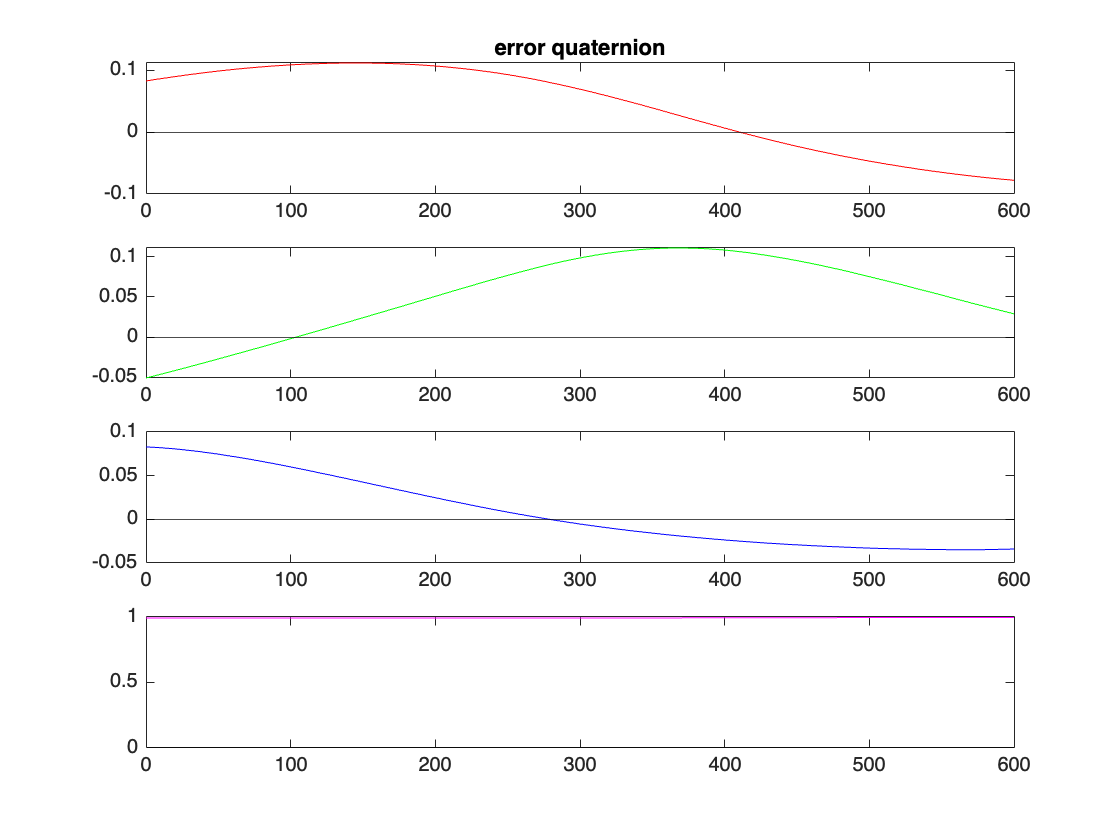

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', figname)
tiledlayout(4, 1), nexttile
plot(t_, qe(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title('error quaternion');
nexttile;
plot(t_, qe(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

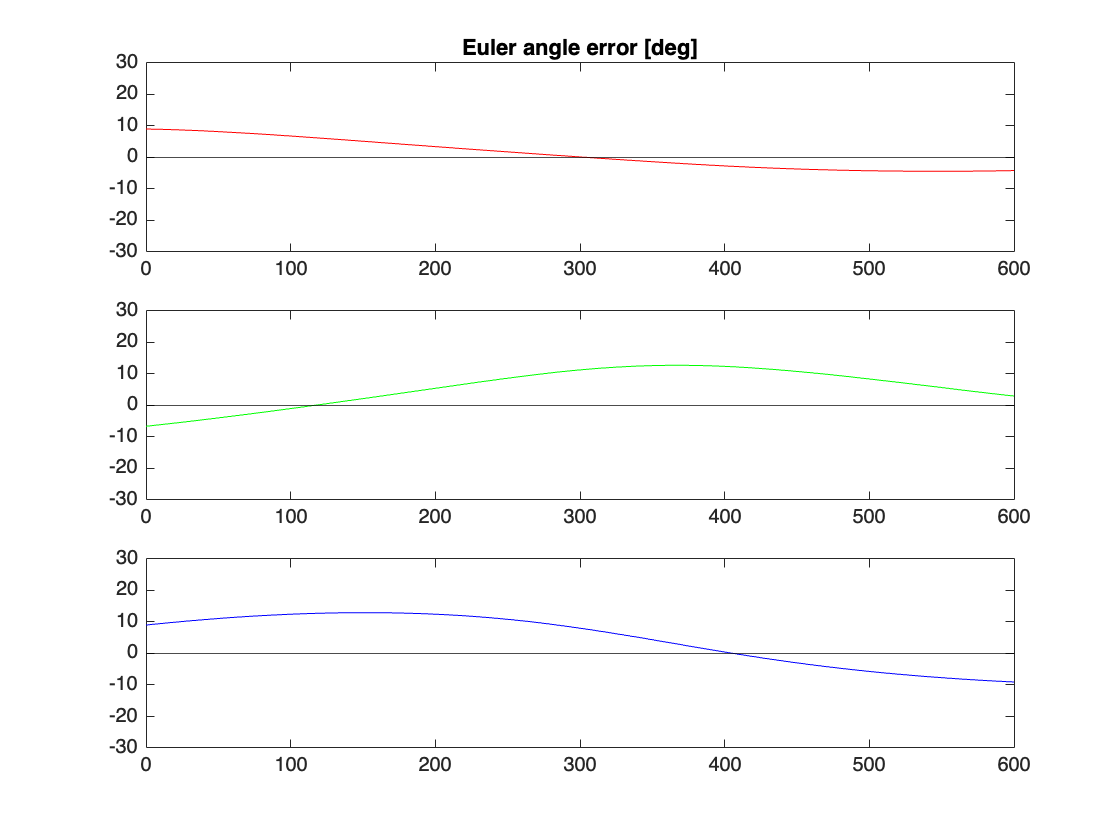


% figure
% tiledlayout(3,1), nexttile
% plot(t_/60, rad2deg(phiE), 'r'); % なんでt_/60をしてるの？
% title('Euler angle error [deg]');
% % xlim([0 60*6]), ylim([-60 60])
% xlim([0 t_(end,1)]), ylim([-60 60])
% nexttile
% plot(t_/60, rad2deg(thetaE), 'g');
% xlim([0 60*6]), ylim([-60, 60]);
% nexttile
% plot(t_/60, rad2deg(psiE), 'b');
% xlim([0 60*6]), ylim([-60 60]);

figname = "eulerAngleError";
figure('Name', figname);
tiledlayout(3,1), nexttile
plot(t_, rad2deg(phiE), 'r'); 
yline(0, '-k');
title('Euler angle error [deg]');
xlim([0 t_(end,1)]), ylim([-30 30])
nexttile
plot(t_, rad2deg(thetaE), 'g');
yline(0, '-k');
xlim([0 t_(end,1)]), ylim([-30 30]);
nexttile
plot(t_, rad2deg(psiE), 'b');
yline(0, '-k');
xlim([0 t_(end,1)]), ylim([-30 30]);
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

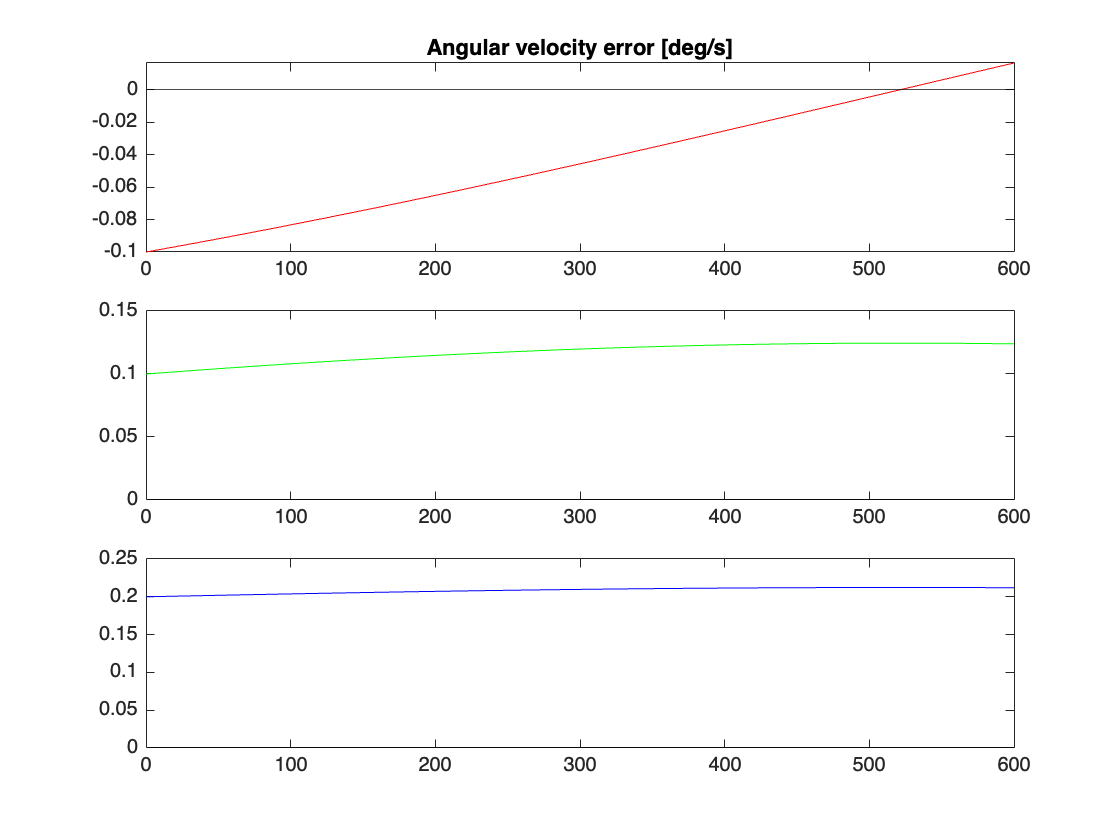


figname = "angularVelocityError";
figure('Name', figname)
tiledlayout(3,1), nexttile
plot(t_, rad2deg(we(:,1)), 'r'); 
yline(0, '-k');
title('Angular velocity error [deg/s]');
xlim([0 t_(end,1)])%, ylim([-60 60])
nexttile
plot(t_, rad2deg(we(:,2)), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])%, ylim([-60, 60]);
nexttile
plot(t_, rad2deg(we(:,3)), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])%, ylim([-60 60]);
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

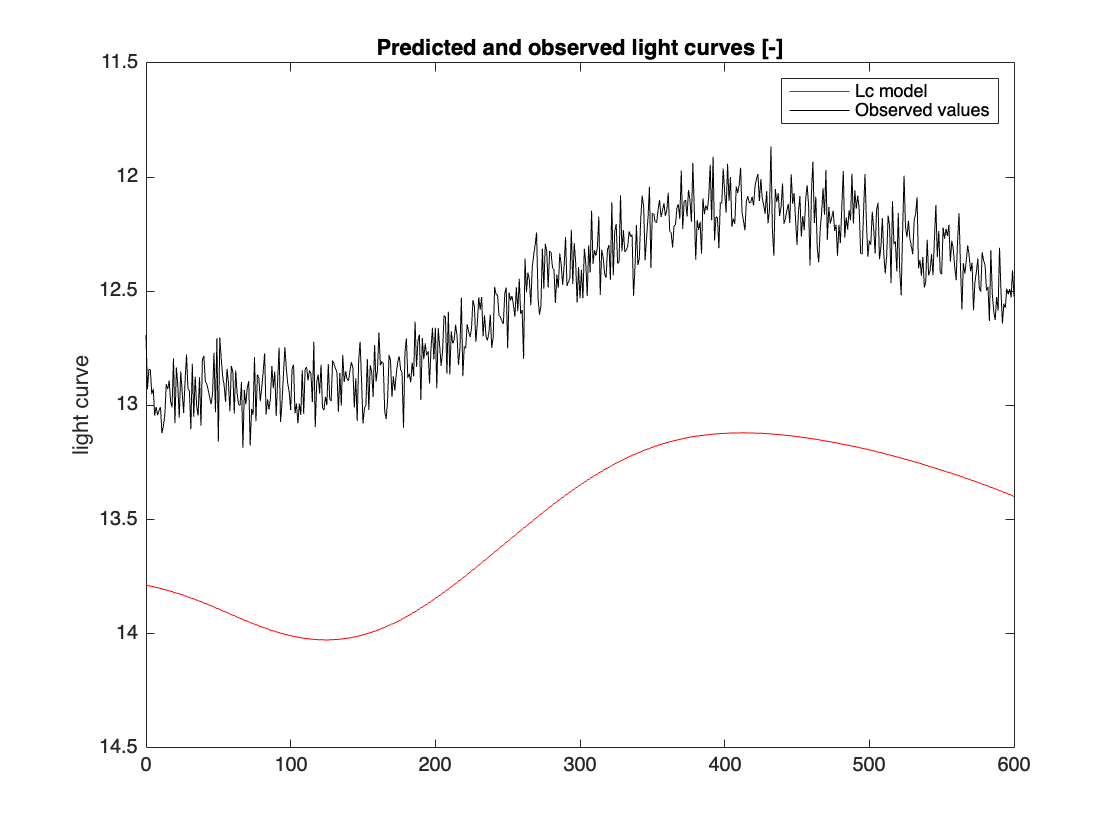


% GPUKF のときだけ 観測モデルの回帰精度を可視化

figname = "observationModelError";
figure('Name', figname)
if strcmp(filter, "GPUKF")
    tiledlayout(2,1), nexttile
    p_GP = plot(t_, ye_GP, 'b'); 
    hold on;
end
p_lc = plot(t_, ye_lc, 'r');
hold on;
p_obs = plot(t_, mAppNoise, 'k-');
hold off;
p_obs.Color(4) = 0.15;
if strcmp(filter, "GPUKF")
    legend([p_GP, p_lc, p_obs], {'GP model', 'Lc model', 'Observed values'})
elseif strcmp(filter, "UKF")
    legend([p_lc, p_obs], {'Lc model', 'Observed values'})
end
title('Predicted and observed light curves [-]');
xlim([0 t_(end,1)])%, ylim([-60 60])
ylabel("light curve")
set(gca, 'YDir', 'reverse')

if strcmp(filter, "GPUKF")
    nexttile
    plot(t_, yee, 'g');
    yline(0, '-k');
    xlim([0 t_(end,1)])%, ylim([-60, 60]);
    xlabel("time [s]");
    ylabel("litht curve error between GP model and lc model")
end
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

tEnd = toc(tStart) / 60; % [min]
strcat("calculation time [min] : ", num2str(tEnd))

ans = "calculation time [min] : 1.1405"